# calculate the TR FI under the context of tumour monitoring

clc
clear
addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
% rmpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\MCXStudio'))
% rmpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\mcx'))
% addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\MCXStudio'))
addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\MCX\mcx_git\iso2mesh'))

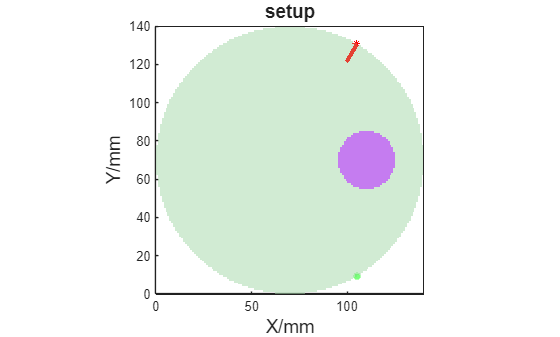

%% 2D CSF simulation main simulation
save_flag = 0; % 0 is not saving any picture
clear cfg_csf;

% % % % ------------general setting---------
cfg_csf.nphoton = 1.5e8;
cfg_csf.gpuid = '11'; % use two GPUs
cfg_csf.workload = [10,10];  % evenly use the two GPUs
cfg_csf.autopilot = 1;
cfg_csf.maxdetphoton = cfg_csf.nphoton;
brain_radius = 70;
cfg_csf.vol = permute(uint8(zeros([2*brain_radius,2*brain_radius])), [3, 1, 2]); % from 2d to 3d
cfg_csf.tstart = 0;
cfg_csf.tend = 3e-9;
cfg_csf.tstep = 1e-10;
cfg_csf.debuglevel = 'P'; % show progress bar
cfg_csf.unitinmm = 1;
cfg_csf.issrcfrom0 = 1;  % 1-first voxel is [0 0 0], [0]- first voxel is [1 1 1]
% % % % -----------general setting end------------

% % % % build indices for the voxels, use voxel center
center_pos = [brain_radius brain_radius];
[grid_z,grid_y] = ndgrid(linspace(2*brain_radius-0.5,0.5,2*brain_radius),linspace(0.5,2*brain_radius-0.5,2*brain_radius));

dmua_tumour = 0.02; % difference in mua because of tumour

% % % % set brain segmentation
% % % % type [0 air, 1 GM, 2 CSF]
cfg_csf.prop = [0 0 1 1;
    0.033 1 0 1.33;
    0.0420 0.01 0 1.33
    0.033+dmua_tumour 1 0 1.33];

D_from_center = sqrt((grid_z-center_pos(1)).^2+(grid_y-center_pos(2)).^2);
csf_radius = [49 49+3];

for i = 1:size(cfg_csf.vol,2)
    for j = 1:size(cfg_csf.vol,3)
        switch true
            case D_from_center(i,j)>=csf_radius(1)&&D_from_center(i,j)<csf_radius(2)
                cfg_csf.vol(1, i, j) = 1;
            case D_from_center(i,j)<=brain_radius
                cfg_csf.vol(1, i, j) = 1;
        end
    end
end

% % % % source set---------------------------------------
source_radius = brain_radius; source_angle_rad =  pi/3;
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
meas_radius = brain_radius; meas_angle_rad =  - pi/3; % pi/2 -0.5 pi/2+0.01
mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
cfg_csf.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
cfg_csf.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)
cfg_csf.srctype = 'pencil';
% % % %  source set end-----------------------------------

% % % % det set
cfg_csf.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 2];
% % % %  det set end

tumour_position = 40;

% % % % ----------set tumour-------------------
tuc_pos = [tumour_position 0];
tuC = [center_pos(1)-tuc_pos(1) center_pos(2)+tuc_pos(2)];
tuR = 15;
D2C = sqrt((grid_z-tuC(1)).^2+(grid_y-tuC(2)).^2);
for i = 1:size(cfg_csf.vol,2)
    for j = 1:size(cfg_csf.vol,3)
        if D2C(i,j)<=tuR
            cfg_csf.vol(1, i, j) = 3;
        end
    end
end
% % % % ----------set tumour end-------------------

% set tumour mask
tumour_mask = squeeze(cfg_csf.vol);
tumour_mask(find(tumour_mask~=3))=0;
tumour_mask(find(tumour_mask==3))=1;
tumour_mask = rot90(tumour_mask);
% figure;imagesc(tumour_mask);

% % % % ----------show the setup
figure,mcxpreview(cfg_csf); title('setup',FontSize=14); view([90,0]);
% figure,imagesc(double(squeeze(cfg_csf.vol)))
ylabel('X/mm',FontSize=14)
zlabel('Y/mm',FontSize=14)

## test to run the MCX once

% [~, detpt_csf, ~, ~] = mcxlab(cfg_csf);
% weight = sum(mcxdetweight(detpt_csf,cfg_csf.prop,cfg_csf.unitinmm));
% tpsf = mcxdettpsf(detpt_csf,1,cfg_csf.prop,[cfg_csf.tstart,cfg_csf.tend,cfg_csf.tstep]);
% plot(tpsf)

## run the batch simulation

cfg_csf.outputtype = 'flux';
rng('default')

% % % % initial variables
source_angle = linspace(-pi/4,0,5)';
det_angle = linspace(-pi/4,pi/4,9)';
weight = zeros(size(det_angle,1)*size(source_angle,1),1);
weight_p = zeros(size(det_angle,1)*size(source_angle,1),1);
tpsf = zeros(length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1,size(det_angle,1)*size(source_angle,1));
tpsf_p = zeros(length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1,size(det_angle,1)*size(source_angle,1));
jacobians = zeros(size(cfg_csf.vol,2),size(cfg_csf.vol,3), ...
    round((cfg_csf.tend - cfg_csf.tstart) / cfg_csf.tstep),size(det_angle,1)*size(source_angle,1));
dmua = 0.0001;

h = waitbar(0, 'processing...');

for i = 1:size(det_angle,1)*size(source_angle,1)
    waitbar(i/(size(det_angle,1)*size(source_angle,1)),h,sprintf('finished %d%%', round(i/(size(det_angle,1)*size(source_angle,1))*100)));
    [im,is] = ind2sub([size(det_angle,1),size(source_angle,1)],i);

    source_radius = brain_radius; source_angle_rad =  source_angle(is);
    meas_radius = brain_radius; meas_angle_rad = det_angle(im) ;

    src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
    mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
    cfg_csf.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
    cfg_csf.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 2];
    cfg_csf.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)

    cfg_csf.seed = randi(cfg_csf.nphoton);
    evalc('[~, detpt_csf, ~, seeds] = mcxlab(cfg_csf);'); % no output information

    if ~isempty(detpt_csf.data)
        weight(i) = sum(mcxdetweight(detpt_csf,cfg_csf.prop,cfg_csf.unitinmm));
        tpsf(:,i) = mcxdettpsf(detpt_csf,1,cfg_csf.prop,[cfg_csf.tstart,cfg_csf.tend,cfg_csf.tstep]);
        prop_p = cfg_csf.prop;
        prop_p(4,1) = prop_p(4,1) + dmua;
        weight_p(i) = sum(mcxdetweight(detpt_csf,prop_p,cfg_csf.unitinmm));
        tpsf_p(:,i) = mcxdettpsf(detpt_csf,1,prop_p,[cfg_csf.tstart,cfg_csf.tend,cfg_csf.tstep]);
        newcfg = cfg_csf;
        newcfg.seed = seeds.data;
        newcfg.outputtype = 'jacobian';
        newcfg.detphotons = detpt_csf.data;
        evalc('[jaco, ~, ~, ~] = mcxlab(newcfg);'); % no output information
        jacobians(:,:,:,i) = -rot90(squeeze(double(jaco.data)),1).* weight(i);
    else
        continue;
    end
end
delete(h);

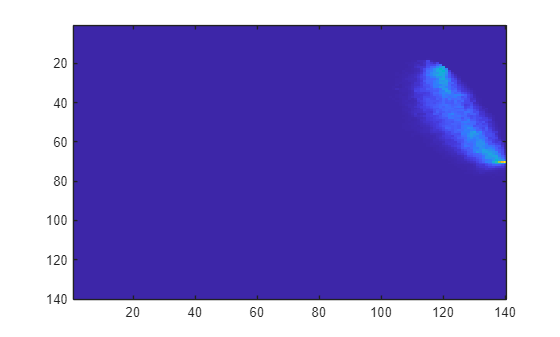

close all
figure;imagesc(rot90(squeeze(sum(jaco.data,4))))

## calculate CW FI

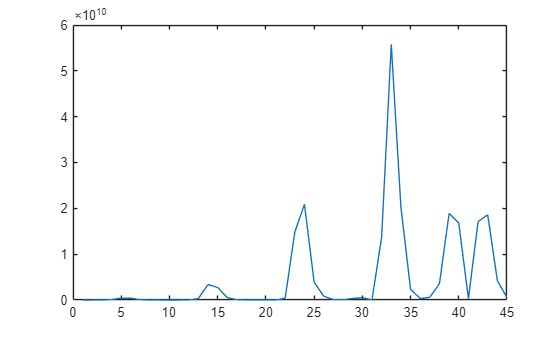

% Convert amplitude to counts per second (cps)
% input_power_density = 3e-3; % maximum safty threshold 3mw/mm^2
% input_power_v = [1e-4 5e-4 1e-3 3e-3]; % W/mm^2
input_power_v =  3e-3; % W/mm^2
amplitude = weight./cfg_csf.nphoton; % normalized
amplitude_p = weight_p./cfg_csf.nphoton;

Fisher_result_batch_csf = zeros(length(amplitude),length(input_power_v));
PC_batch_csf = zeros(length(amplitude),length(input_power_v));
dIdmua_batch_csf = zeros(length(amplitude),length(input_power_v));
ind_result = 1;
addpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\tomography241015\NIRfast_code_241118\nirfast_fisher_numerical_311224')

h = 6.626e-34; % Planck constant in Js
lambda = 800e-9; % wavelength in m
c = 299792453;
sp_eng = h.*c/(lambda); % single photon energy
exposure_time = 1;
bandwidth = 1/exposure_time/2;

for input_power_density =  input_power_v

    photon_counts = round(amplitude.*input_power_density/sp_eng*exposure_time*1); % exposure time 0.1s and area 1mm^2
    photon_counts_p = round(amplitude_p.*input_power_density/sp_eng*exposure_time*1); % exposure time 0.1s and area 1mm^2

    %---------no round-up------------
    % photon_counts = (amplitude.*input_power_density/sp_eng*exposure_time*1); % exposure time 0.1s and area 1mm^2
    % photon_counts_p = (amplitude_p.*input_power_density/sp_eng*exposure_time*1); % exposure time 0.1s and area 1mm^2
    %---------no round-up------------

    PC_batch_csf(:,ind_result) = photon_counts;

    pc_threshold = 1e8*exposure_time; % the threshold of SPAD max cps
    dI_dmua = (photon_counts_p-photon_counts)./dmua; % calculate how the intensity change with tumour radius
    % dI_dmua = dI_dmua.*(abs(dI_dmua)>1);

    dIdmua_batch_csf(:,ind_result) = dI_dmua;

    % % % % distinguish according to threshold
    Poisson_ind = photon_counts<=pc_threshold;
    Gaussian_ind = photon_counts>pc_threshold;

    % % % % gaussian noise level
    nep = 1e-13; % W/sqrt(Hz)
    Gaussian_std = nep*sqrt(bandwidth)/sp_eng*exposure_time;
    % std of CPS, exposure time 0.1s

    % Fisher_result = dI_dmua.^2.*1./photon_counts.*Poisson_ind; % Poisson noise
    Fisher_result = dI_dmua.^2.*1./photon_counts; % Poisson noise

    % Fisher_result(isnan(Fisher_result)) = 0;
    % 
    % % % % % Gaussian noise+poisson noise
    % % for i = 1:length(Fisher_result(:))
    % parfor (i = 1:length(Fisher_result(:)),4)
    %     if Gaussian_ind(i) == 1
    %         Fisher_result(i) = calculate_Gau_Pos_FI(Gaussian_std,photon_counts(i),dI_dmua(i));
    %     end
    % end

    Fisher_result_batch_csf(:,ind_result) = Fisher_result;
    ind_result = ind_result+1;
end

figure;plot(Fisher_result_batch_csf)

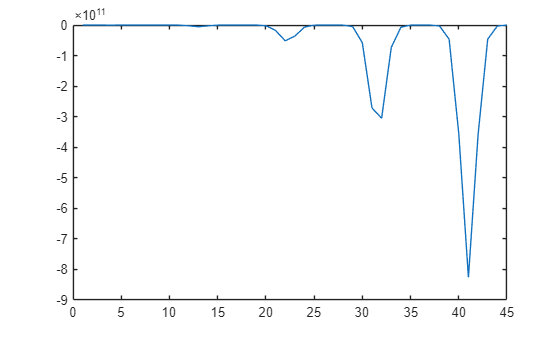

figure; plot(dIdmua_batch_csf)

## calculate TR FI

h = 6.626e-34; % Planck constant in Js
lambda = 800e-9; % wavelength in m
c = 299792453;
sp_eng = h.*c/(lambda); % single photon energy
exposure_time = 0.1;
bandwidth = 1/exposure_time/2;
mpe = 3e-3; % w/mm^2
rep_rate = 80e6; % repetetion rate Hz
single_pulse_energy = mpe./rep_rate; % J/mm^2
single_pulse_photon_count = single_pulse_energy./sp_eng;
exposure_time_tr = 1; % unit in second, the exposure time for the TCSPC
tpsf_normalized = tpsf./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;

FiMean_m0 = zeros(size(tpsf_normalized,2),1);
FiMean_m1 = zeros(size(tpsf_normalized,2),1);
FiMean_m2 = zeros(size(tpsf_normalized,2),1);
FiMean_m2c = zeros(size(tpsf_normalized,2),1);
dm0_dbin = zeros(size(tpsf));
dm1_dbin = zeros(size(tpsf));
dm2_dbin = zeros(size(tpsf));
dm2c_dbin = zeros(size(tpsf));

watbar = waitbar(0);
for i = 1:size(tpsf_normalized,2)
    waitbar(i/size(tpsf_normalized,2),watbar,sprintf('finished %d%%', round(100*i/size(tpsf_normalized,2))));
    [FiMean_m0(i),FiMean_m1(i),FiMean_m2(i),FiMean_m2c(i),dm0_dbin(:,i),dm1_dbin(:,i),dm2_dbin(:,i),dm2c_dbin(:,i)] = ...
    TR_FisherMean_calculation(tpsf_normalized(:,i)',1e6,cfg_csf.tstep.*1e12);
end
close(watbar);

jacobians_pc = jacobians./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;

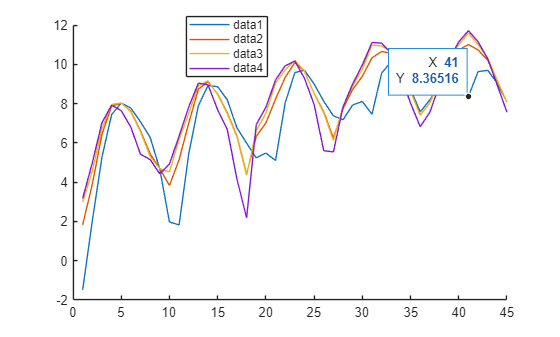

FI_mua_m0 = sum(squeeze(sum(double(tumour_mask).*(jacobians_pc),[1 2])).*dm0_dbin,1)'.^2.*FiMean_m0;
FI_mua_m1 = sum(squeeze(sum(double(tumour_mask).*(jacobians_pc),[1 2])).*dm1_dbin,1)'.^2.*FiMean_m1;
FI_mua_m2 = sum(squeeze(sum(double(tumour_mask).*(jacobians_pc),[1 2])).*dm2_dbin,1)'.^2.*FiMean_m2;
FI_mua_m2c = sum(squeeze(sum(double(tumour_mask).*(jacobians_pc),[1 2])).*dm2c_dbin,1)'.^2.*FiMean_m2c;

figure;
hold on
plot(log10(FI_mua_m0));
plot(log10(FI_mua_m1));
plot(log10(FI_mua_m2));
plot(log10(FI_mua_m2c));
legend

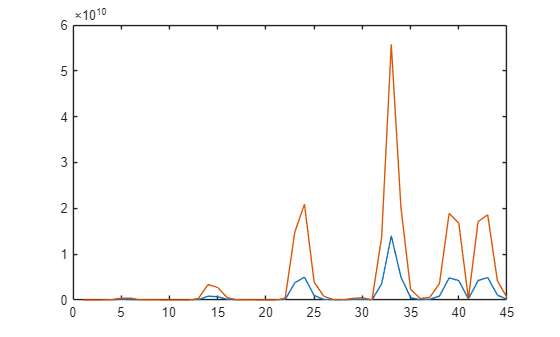


figure;
plot(FI_mua_m0);hold on
plot(Fisher_result_batch_csf);

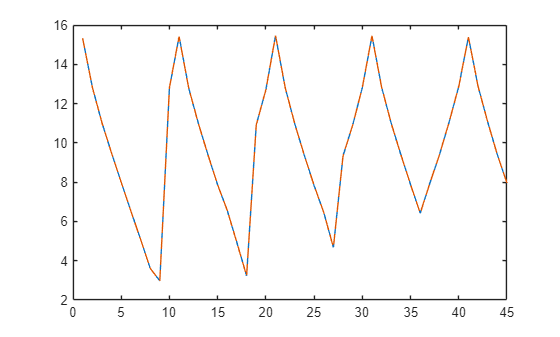

figure;
plot(log10(photon_counts)); hold on;
plot(log10(sum(tpsf_normalized,1)),'--')

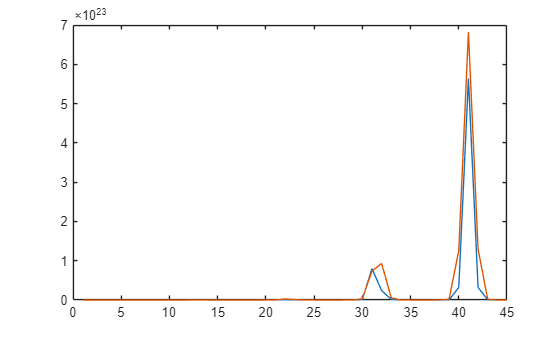


figure
new_di_dmua = sum(squeeze(sum(double(tumour_mask).*(jacobians_pc),[1 2])),1)';
plot(abs(new_di_dmua).^2); hold on
plot(abs(dIdmua_batch_csf).^2); hold on;

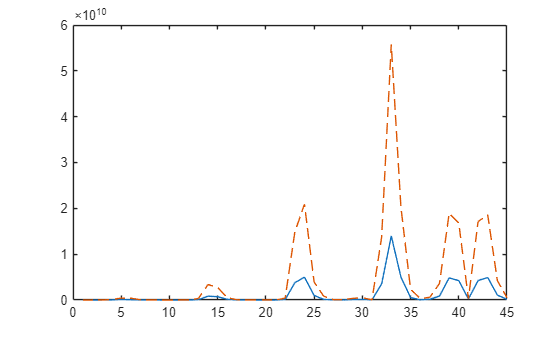

figure
plot(new_di_dmua.^2./sum(tpsf_normalized,1)'); hold on
plot(dIdmua_batch_csf.^2./photon_counts,'--'); hold on;

## show result

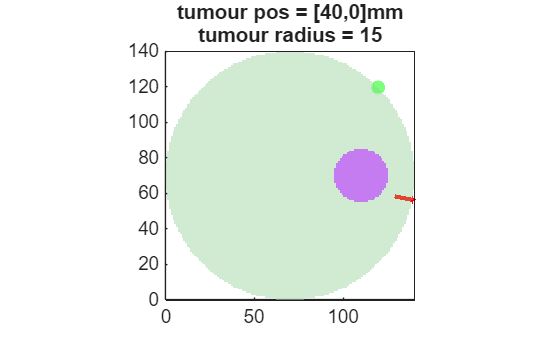

target_sd_pair = 36;

[im,is] = ind2sub([size(det_angle,1),size(source_angle,1)],target_sd_pair);

source_radius = brain_radius; source_angle_rad =  source_angle(is);
meas_radius = brain_radius; meas_angle_rad =  det_angle(im) ;
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
cfg_csf.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
cfg_csf.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 4];
cfg_csf.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)

figure;mcxpreview(cfg_csf); title(sprintf('tumour pos = [%d,%d]mm\ntumour radius = %d',tuc_pos(1),tuc_pos(2) ...
    ,tuR)); view([90,0]);
colormap('parula')
ax = gca; ax.FontSize = 14;

## test function, proves that Gaussian approximation is correct

% rng('default')
% 
% lambdas = round(tpsf_normalized(:,i)');
% rndnum = 1e5;
% binWidth =  cfg_csf.tstep*1e12;
% num_of_pdf_bins = 20;
% 
% lambda_rep = repmat(lambdas,[rndnum,1]);
% 
% obs = poissrnd(lambda_rep,rndnum,length(lambdas)); % default poisson noise
% number_of_timebins = length(lambdas); % number of time bins
% edge_indx = round(linspace(1,rndnum,num_of_pdf_bins+1));
% 
% tSeries = binWidth*(0:length(lambdas)-1)'+binWidth/2;
% 
% m0 = sum(obs,2);
% Em0 = mean(m0);
% stdm0 = std(m0);
% lambdas_p_m0 = round(1.6*stdm0*ones(number_of_timebins,1)); % perturbation for each timebin
% 
% m1 = sum(tSeries'.*obs,2)./sum(obs,2);
% Em1 = mean(m1);
% stdm1 = std(m1);
% dm1_dbin = (tSeries-Em1)./Em0;
% lambdas_p_m1 = round(1.6*stdm1./dm1_dbin); % perturbation for each timebin
% 
% m2 = sum(tSeries'.^2.*obs,2)./sum(obs,2);
% Em2 = mean(m2);
% stdm2 = std(m2);
% dm2_dbin = (tSeries.^2-Em2)./Em0;
% lambdas_p_m2 = round(0.5*stdm2./dm2_dbin); % perturbation for each timebin
% 
% m2c = m2-m1.^2;
% Em2c = mean(m2c);
% stdm2c = std(m2c);
% dm2c_dbin = ((tSeries-Em1).^2-Em2c)./Em0;
% lambdas_p_m2c = round(0.5*stdm2c./dm2c_dbin); % perturbation for each timebin
% 
% m0_sort = sort(m0);
% m0_equal_filling_edge = m0_sort(edge_indx);
% m0_equal_filling_edge = [-Inf;m0_equal_filling_edge(2:end-1);  +Inf];
% 
% m1_sort = sort(m1);
% m1_equal_filling_edge = m1_sort(edge_indx);
% m1_equal_filling_edge = [-Inf; m1_equal_filling_edge(2:end-1);  +Inf];
% 
% m2_sort = sort(m2);
% m2_equal_filling_edge = m2_sort(edge_indx);
% m2_equal_filling_edge = [-Inf;  m2_equal_filling_edge(2:end-1); +Inf];
% 
% m2c_sort = sort(m2c);
% m2c_equal_filling_edge = m2c_sort(edge_indx);
% m2c_equal_filling_edge = [-Inf ; m2c_equal_filling_edge(2:end-1); +Inf];
% 
% % % % % def the PDF matrix for each moment
% m0_pdf = zeros(num_of_pdf_bins,number_of_timebins);
% m0_pdf_p = zeros(num_of_pdf_bins,number_of_timebins);
% 
% m1_pdf = zeros(num_of_pdf_bins,number_of_timebins);
% m1_pdf_p = zeros(num_of_pdf_bins,number_of_timebins);
% 
% m2_pdf = zeros(num_of_pdf_bins,number_of_timebins);
% m2_pdf_p = zeros(num_of_pdf_bins,number_of_timebins);
% 
% m2c_pdf = zeros(num_of_pdf_bins,number_of_timebins);
% m2c_pdf_p = zeros(num_of_pdf_bins,number_of_timebins);
% 
% % figure;
% % plot(lambdas_p_m1);hold on;
% % plot(lambdas_p_m2);hold on;
% % plot(lambdas_p_m2c);hold on;
% 
% TR_counts_p = lambdas;
% ip = 20;
% % TR_counts_p(ip) = TR_counts_p(ip)+lambdas_p_m2(ip);
% TR_counts_p(ip) = TR_counts_p(ip)+lambdas_p_m2c(ip);
% 
% [m0_p,m1_p,m2_p,m2c_p] = cal_random_moments_new(TR_counts_p,rndnum,binWidth,'poisson');
% 
% % m0_pdf = histcounts(m0,m0_equal_filling_edge,'Normalization', 'probability');
% % m0_pdf_p = histcounts(m0_p,m0_equal_filling_edge,'Normalization', 'probability');
% 
% % m1_pdf = histcounts(m1,m1_equal_filling_edge,'Normalization', 'probability');
% % m1_pdf_p = histcounts(m1_p,m1_equal_filling_edge,'Normalization', 'probability');
% 
% m2_pdf= histcounts(m2,m2_equal_filling_edge,'Normalization', 'probability');
% m2_pdf_p = histcounts(m2_p,m2_equal_filling_edge,'Normalization', 'probability');
% 
% m2c_pdf = histcounts(m2c,m2c_equal_filling_edge,'Normalization', 'probability');
% m2c_pdf_p = histcounts(m2c_p,m2c_equal_filling_edge,'Normalization', 'probability');
% 
% % plot(m0_pdf_p(:,i)),hold on
% % plot(m0_pdf(:,i)),hold on
% %
% % plot(m1_pdf_p(:,i)),hold on
% % plot(m1_pdf(:,i)),hold on
% %
% figure
% plot(m2_pdf_p),hold on
% plot(m2_pdf),hold on
% 
% figure;
% plot(m2c_pdf_p),hold on
% plot(m2c_pdf),hold on
% %
% % plot(m2c_pdf_p(:,i)),hold on
% % plot(m2c_pdf(:,i)),hold on
% 
% % dlnM0 = (log(m0_pdf_p)-log(m0_pdf))./lambda_p;
% % dlnM1 = (log(m1_pdf_p)-log(m1_pdf))./lambda_p;
% dlnM2 = sum(((log(m2_pdf_p)-log(m2_pdf))./lambdas_p_m2(ip)./dm2_dbin(ip)).^2.*m2_pdf)
% 
% 1/var(m2)
% % dlnM2c = (log(m2c_pdf_p)-log(m2c_pdf))./lambda_p;
% dlnM2c = sum(((log(m2c_pdf_p)-log(m2c_pdf))./lambdas_p_m2c(ip)./dm2c_dbin(ip)).^2.*m2c_pdf)
% 1/var(m2c)
% % The conclusion is that you can use 1/var as the Fisher Information

## data analyse

SD_index = 41;

%----------------show the dM/dbin----------
figure;
% plot(log10(dm1_dbin(:,SD_index).^2),LineWidth=2), hold on
plot(log10(dm2_dbin(:,SD_index).^2),LineWidth=2), hold on
plot(log10(dm2c_dbin(:,SD_index).^2),LineWidth=2), hold on
figure
plot((dm2_dbin(:,SD_index).^2)./(dm2c_dbin(:,SD_index).^2),LineWidth=2), hold on
mean((dm2_dbin(:,SD_index).^2)./(dm2c_dbin(:,SD_index).^2))

ans = 1.4332

% plot((dm2c_dbin(:,SD_index).^2),LineWidth=2), hold on
% legend('M1','M2','M2c')
%----------------show the dM/dbin----------

%----------show the 1/variance of moments------------
1/FiMean_m1(SD_index)

ans = 2.3329e-13

sum(dm1_dbin(:,SD_index).^2.*tpsf_normalized(:,SD_index))

ans = 2.3321e-13


1/FiMean_m2(SD_index)

ans = 2.7625e-08

sum(dm2_dbin(:,SD_index).^2.*tpsf_normalized(:,SD_index))

ans = 2.7627e-08


1/FiMean_m2c(SD_index)

ans = 1.4572e-08

sum(dm2c_dbin(:,SD_index).^2.*tpsf_normalized(:,SD_index))

ans = 1.4577e-08


%----------show the 1/variance of moments------------


%--------------show the dM/dmua----------
dm1_dmua = sum(squeeze(sum(double(tumour_mask).*(jacobians_pc),[1 2])).*dm1_dbin,1)';
dm2_dmua = sum(squeeze(sum(double(tumour_mask).*(jacobians_pc),[1 2])).*dm2_dbin,1)';
dm2c_dmua = sum(squeeze(sum(double(tumour_mask).*(jacobians_pc),[1 2])).*dm2c_dbin,1)';


% figure
% plot(dm1_dmua(1)), hold on
% plot(dm2_dmua(1))
% plot(dm2c_dmua(1))
% legend('M1','M2','M2c')

dm1_dmua(SD_index).^2

ans = 0.0237

dm2_dmua(SD_index).^2

ans = 1.0594e+04

dm2c_dmua(SD_index).^2

ans = 7.4601e+03

%--------------show the dM/dmua----------

%-------------
FI_mua_m1(SD_index)

ans = 1.0157e+11

FI_mua_m2(SD_index)

ans = 3.8351e+11

FI_mua_m2c(SD_index)

ans = 5.1196e+11

%--------------
sd_index = 41;

close all

load("D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\Fisher_Information_paper\MCX_CW\results1_TRFI_53mm.mat")
dbin_dmua = squeeze(sum(double(tumour_mask).*(jacobians_pc),[1 2]));
figure(1);
plot(dbin_dmua(:,1)), hold on
figure(2);
plot(log(tpsf_normalized(:,sd_index))), hold on
figure(3);
plot(dm1_dbin(:,sd_index)), hold on
plot(dm2_dbin(:,sd_index))
plot(dm2c_dbin(:,sd_index))

sum(dbin_dmua(:,1))

ans = -5.0867e+06

FI_mua_m0(sd_index)

ans = 1.5258e+15

FI_mua_m1(sd_index)

ans = 1.4684e+16

FI_mua_m2(sd_index)

ans = 1.3715e+16

FI_mua_m2c(sd_index)

ans = 1.1808e+16


load("D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\Fisher_Information_paper\MCX_CW\results1_TRFI_45mm.mat")
dbin_dmua = squeeze(sum(double(tumour_mask).*(jacobians_pc),[1 2]));
figure(1);
plot(dbin_dmua(:,1)), hold on
figure(2);
plot(log(tpsf_normalized(:,sd_index))), hold on
sum(dbin_dmua(:,1))

ans = -8.2142e+06

figure(3)
plot(dm1_dbin(:,sd_index)); hold on
plot(dm2_dbin(:,sd_index))
plot(dm2c_dbin(:,sd_index))
FI_mua_m0(sd_index)

ans = 7.2772e+10

FI_mua_m1(sd_index)

ans = 1.4047e+13

FI_mua_m2(sd_index)

ans = 3.1424e+13

FI_mua_m2c(sd_index)

ans = 3.7909e+13

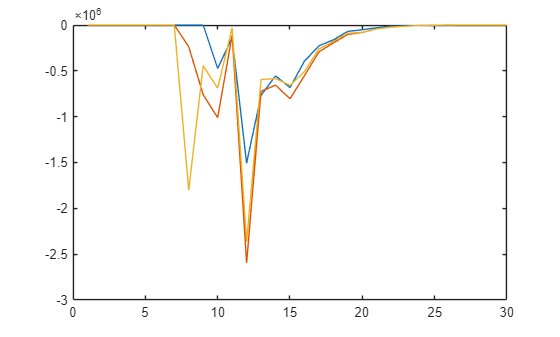


load("D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\Fisher_Information_paper\MCX_CW\results1_TRFI_40mm.mat")
dbin_dmua = squeeze(sum(double(tumour_mask).*(jacobians_pc),[1 2]));
figure(1);
plot(dbin_dmua(:,1)), hold on

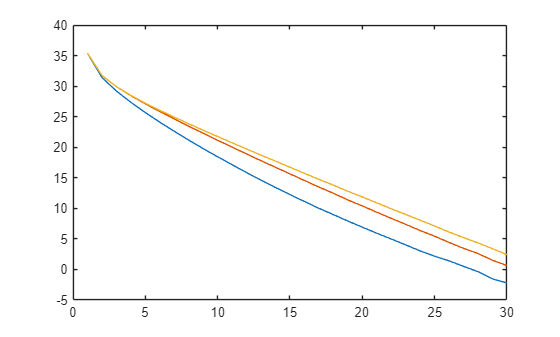

figure(2);
plot(log(tpsf_normalized(:,sd_index))), hold on

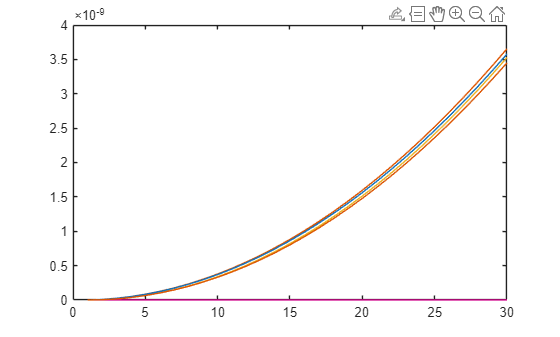

figure(3)
plot(dm1_dbin(:,sd_index)); hold on
plot(dm2_dbin(:,sd_index))
plot(dm2c_dbin(:,sd_index))


sum(dbin_dmua(:,1))

ans = -8.3751e+06

FI_mua_m0(sd_index)

ans = 2.3182e+08

FI_mua_m1(sd_index)

ans = 1.0157e+11

FI_mua_m2(sd_index)

ans = 3.8351e+11

FI_mua_m2c(sd_index)

ans = 5.1196e+11